### PDE Model of Cdk1 Activation and Propagation

Model Parameters.

consts.scale = 10;

% diffusion constant in micro-m^2 min^-1.
consts.Dp = 600;

% EC50 concentrations in nM.
consts.EC50deg = 32;
consts.EC50cdc25 = 35;
consts.EC50wee1 = 30;

Simulation parameters.

% time duration.
consts.tmax = 300;
consts.del_t = 1;

% x range is from -2000 to 2000.
consts.xrange = 2000;

Solve the system of PDEs.

% define time interval and x-mesh.
tspan = linspace(0, consts.tmax, consts.tmax/consts.del_t);
xmesh = linspace(-1*consts.xrange, consts.xrange, 2*consts.xrange); 
% get PDE functions.
pde_funcs = cdk1_act_inact_dt;
% solve PDE!
sol = pdepe(0, ...
    @pde_funcs.Cdk1_PDE, ...
    @pde_funcs.Cdk1_init, ...
    @pde_funcs.Cdk1_boundaries, ...
    xmesh, tspan, [], consts ...
);
disp("PDEs solved");

PDEs solved


% unpack solutions.
cdk1_act = sol(:, 1501:2500, 1);      % active Cdk1 solution.      
cdk1_inact = sol(:, 1501:2500, 2);    % inactive Cdk1 solution.

### Plot Active Cdk1 concentration as a function of time and position.

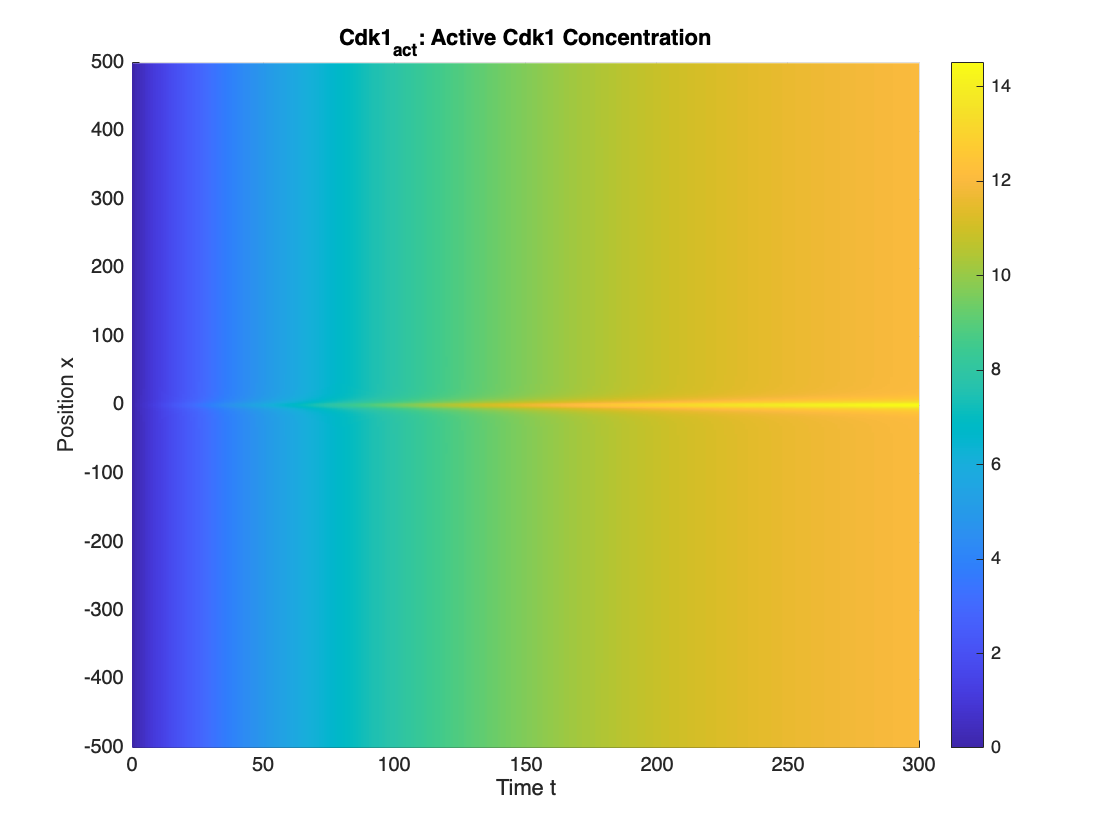

surf(tspan, xmesh(1501:2500), cdk1_act', cdk1_act', 'EdgeColor', 'none');
colorbar;
view(0, 90);
title('Cdk1_{act}: Active Cdk1 Concentration');
xlabel('Time t');
ylabel('Position x');

### ODE Model of Cdk1-APC/C Cell Cycle Oscillator

% sysnthesis rate in nM/min.
ode_params.ksynth =	1;

% rate params in min^-1.
ode_params.adeg	= 0.01;
ode_params.bdeg	= 0.04;
ode_params.acdc25 = 0.16;
ode_params.bcdc25 = 0.80;
ode_params.awee1 = 0.08;
ode_params.bwee1 = 0.40;

% Hill coefficients.
ode_params.ncdc25 = 11;
ode_params.nwee1 = 3.5;
ode_params.ndeg = 17;

% concentrations in nM.
ode_consts.EC50deg = 32;
ode_consts.EC50cdc25 = 35;
ode_consts.EC50wee1	= 30;

Solve the system of ODEs.

% time duration.
ode_consts.tmax = 500;

% initial Cdk1 and Cyclin concentrations are 0.
ode_consts.y_init = [0; 0];

% get ODE functions.
ode_funcs = cdk1_cyclin_ode;

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, ode_params, ode_consts), [0; ode_consts.tmax], ode_consts.y_init);

Unpack and Plot the ODE solutions.

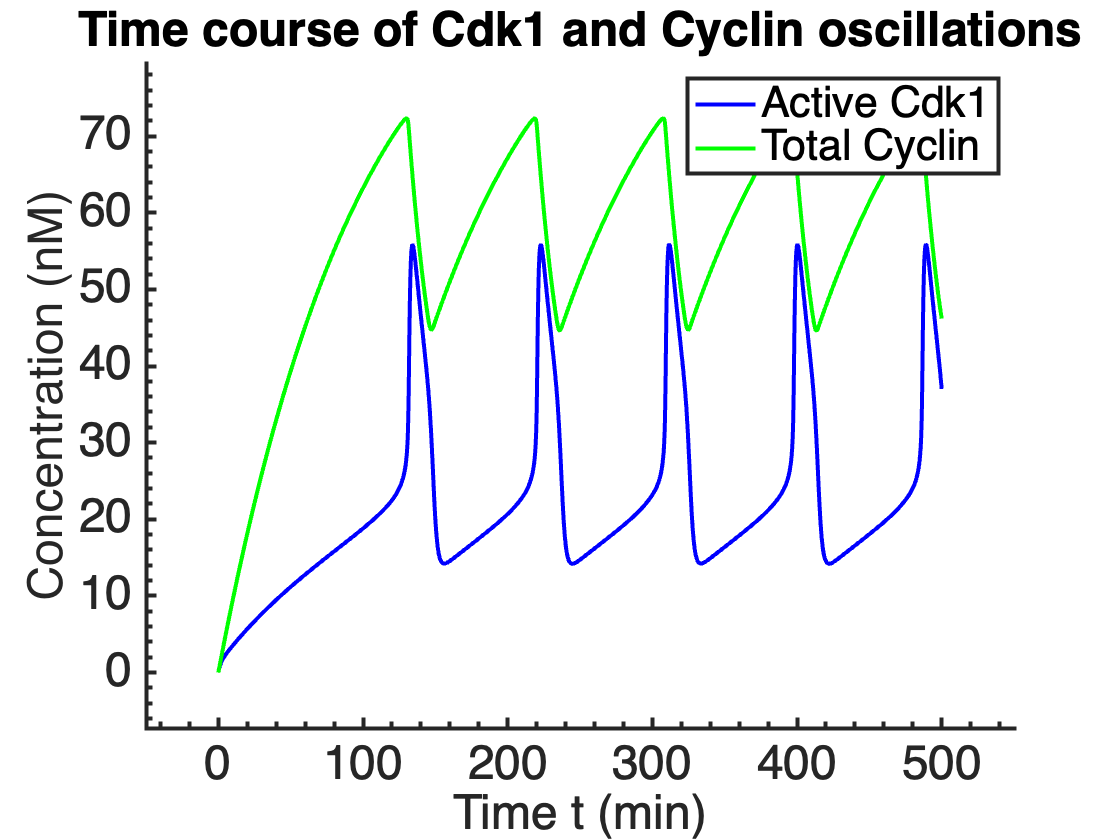

% unpack.
ode_cdk1 = x(:, 1);
ode_cyclin = x(:, 2);
% plot.
figure; hold on;
plot(ode_tout, ode_cdk1, 'Color', 'blue');
plot(ode_tout, ode_cyclin, 'Color', 'green');
title('Time course of Cdk1 and Cyclin oscillations');
xlabel('Time t (min)');
ylabel('Concentration (nM)');
legend('Active Cdk1', 'Total Cyclin');
PrettyFig;

Analytically solve the ODEs to obtain nullcline equations.

**Note: **

- *The analytical solution of the Cdk1 nullcline is hard to solve; hence, this is solved numerically, taking regularly-spaced values of Cyclin concentration. *

- *At the hysteretic region, there are multiple solutions for Cdk1 for a given Cycline concentration; these are obtained by repeated solutions with restricted solution intervals (see cdk1_cyclin_ode.m).*

So the last two argument to the following function call specify the Cyclin concentrations for solving and the expected hyteretic region where multiple solutions are sought, respectively.

[ode_cdk1_nullcline_pts, ode_cyclin_nullcline] = ode_funcs.nullclines(ode_params, ode_consts, linspace(0, 100, 101), [40 60]);

Plot the nullclines.

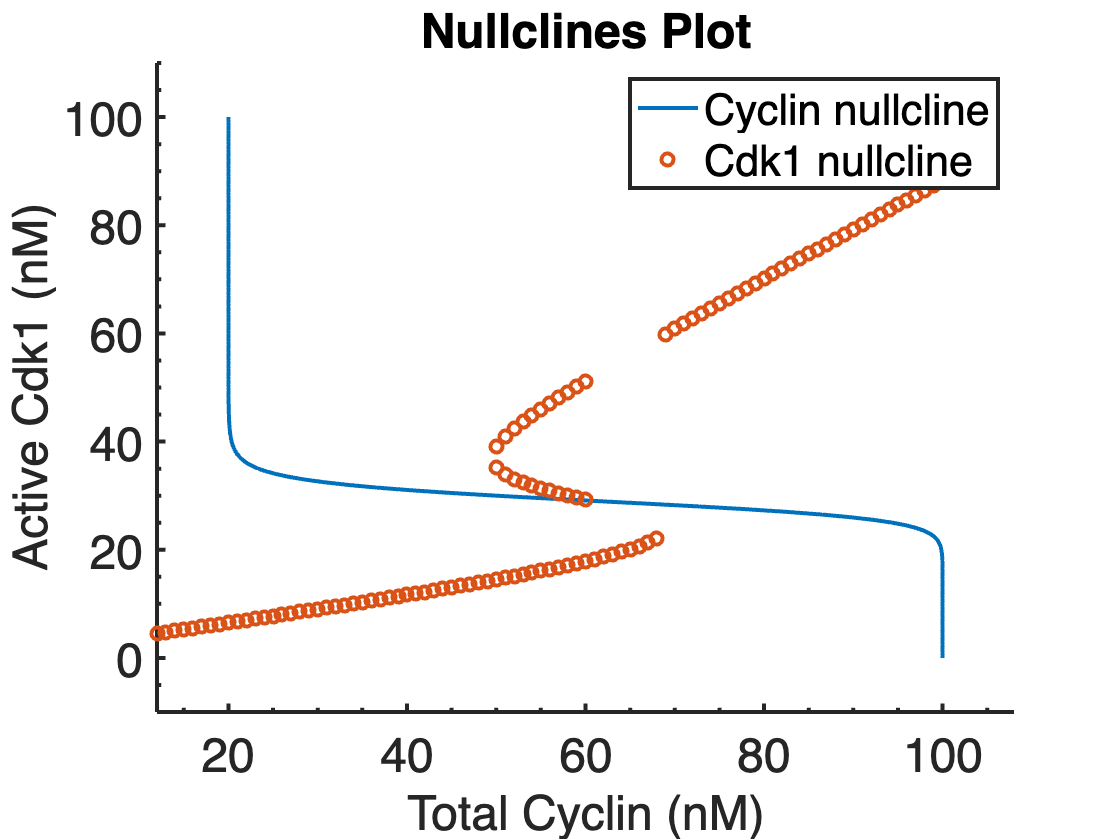

figure; hold on;
plot(double(subs(ode_cyclin_nullcline, sym('Cdk1'), linspace(0, 100, 201))), 0:0.5:100);
scatter(ode_cdk1_nullcline_pts(:, 1), ode_cdk1_nullcline_pts(:, 2));
title('Nullclines Plot');
xlabel('Total Cyclin (nM)');
ylabel('Active Cdk1 (nM)');
legend('Cyclin nullcline', 'Cdk1 nullcline');
PrettyFig;

Plot the vector field against the nullclines to see the oscillation region.

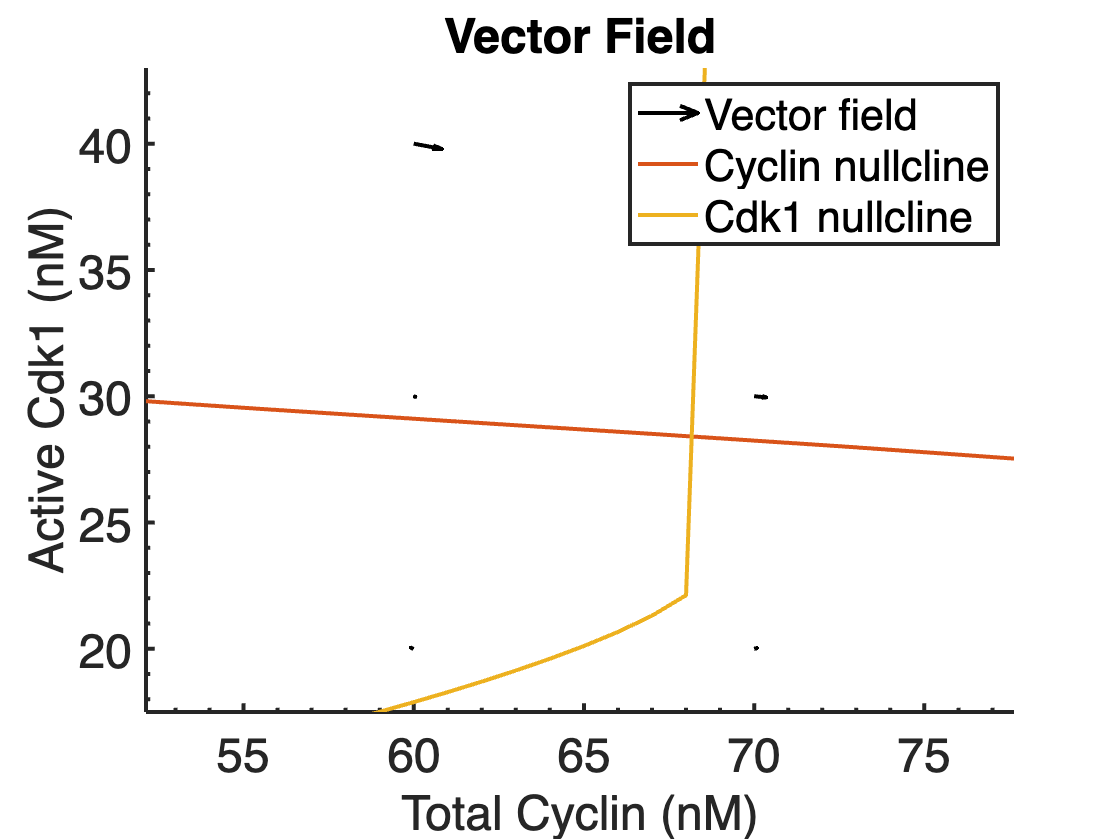

[ode_cdk1_samps, ode_cyc_samps] = meshgrid([0:10:100],[0:10:100]);

% get ODE functions.
ode_funcs = cdk1_cyclin_ode;

% get rate values at all points in the mesh.
dydt = ode_funcs.dydt_array(0, cat(3, ode_cdk1_samps, ode_cyc_samps), ode_params, ode_consts);
figure; zoom on; hold on;
quiver(ode_cdk1_samps, ode_cyc_samps, dydt(:, :, 1)', dydt(:, :, 2)', 'color', 'k');
plot(double(subs(ode_cyclin_nullcline, sym('Cdk1'), linspace(0, 100, 201))), 0:0.5:100);
scatter(ode_cdk1_nullcline_pts(:, 1), ode_cdk1_nullcline_pts(:, 2));
title('Vector Field');
xlabel('Total Cyclin (nM)');
ylabel('Active Cdk1 (nM)');
legend('Vector field', 'Cyclin nullcline', 'Cdk1 nullcline');
PrettyFig